## 关节空间与绳长的映射（各圆盘单元同质化版本）

## 1.命名规定

- 实际最终安装的模型方向如下图所示。下述计算均以正运动学建立时规定的基准点及关节转角为基准。

            根据安装实际，规定各穿线孔的编号，如下图所示。同理定义各孔对应驱动丝编号。

            其中hole_1、hole_2、hole_11、hole_12组仅控制根部关节，根据定义，控制根部关节的四根驱动丝对应为Rope_length(1)、Rope_length(2）、Rope_length(11)、Rope_length(12)。

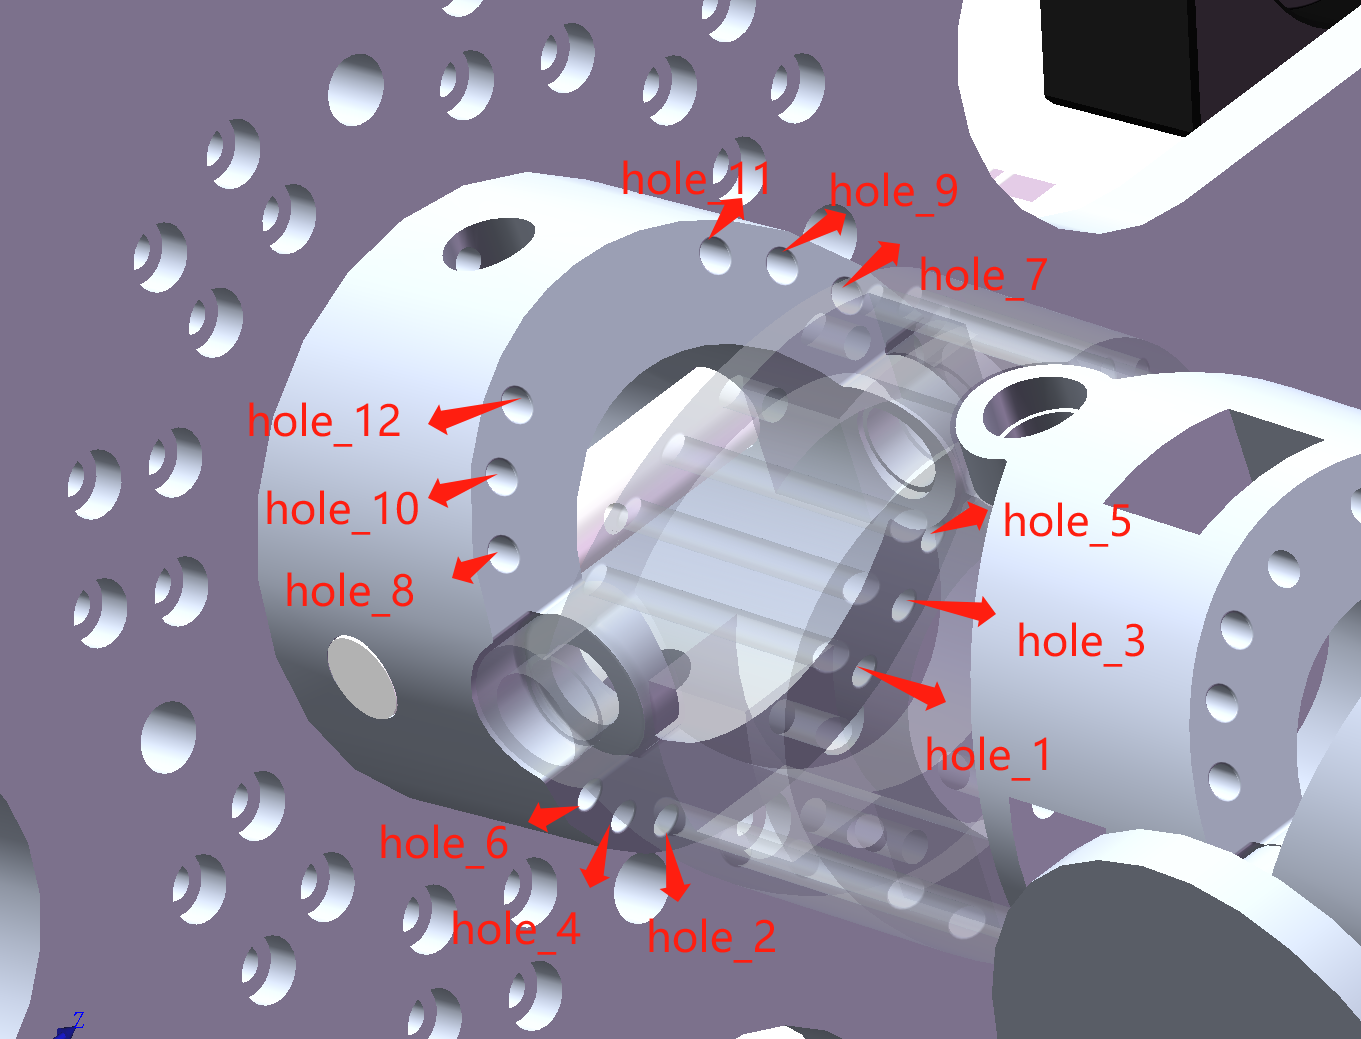

- (2)以下图两个蓝色面之间作为一组进行计算。

        如下图所示，Gap_base为基座圆盘内绳长，为固定值；Gap_1、Gap_2、Gap_3、Gap_4表示每一组圆盘内部的四段绳长，其中Gap_1和Gap_3根据关节转角发生变化，而Gap_2和Gap_4为圆盘内各组孔位对应长度，为固定值。运用12维数组存储各rope对应的Gap的绳长，其中，固定值测量后赋值得到数组如下：

% Gap_2(1:12) = [29.63,29.63,29.09,29.09,29.63,29.63,29.63,29.63,29.09,29.09,29.63,29.63]; %第2个间隙, 固定值
% Gap_4(1:12) = [29.63,29.63,29.09,29.09,29.63,29.63,29.63,29.63,29.09,29.09,29.63,29.63]; %第4个间隙, 固定值
% Gap_base(1:12) = [24.57,24.57,26.11,26.11,28.12,28.12,28.12,28.12,26.11,26.11,24.57,24.57,];%基座圆盘处绳长，固定值

采用12维数组Rope_length来存储当前的绳长：

% Rope_length=zeros(1, 12); %12根绳长的当前长度

    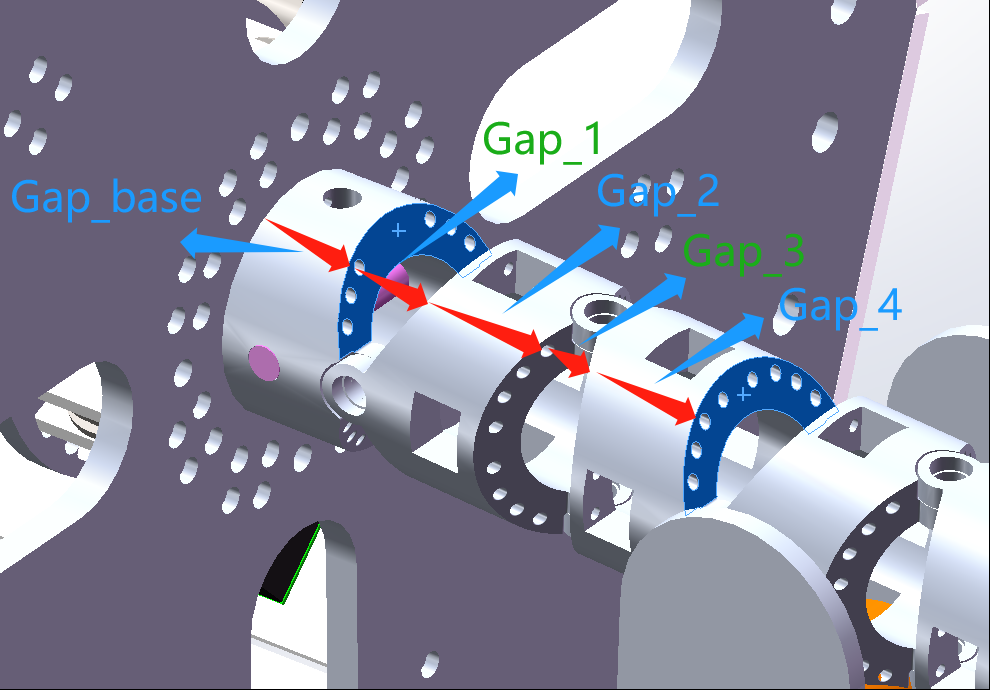

  做简化假设，绳长在间隙间认为是直线。初始时，两相邻面间夹角为beta(零位时均为水平状态，此时beta=50°）：

% beta = pi*50/180; % gap1和gap3的初始角度

 根据测量值，用12维数组存储各对应的Gap处孔心到旋转轴的的垂线长度：

% R_Gap_1(1:12) = [23.03,23.03,18.82,18.82,13.33,13.33,13.33,13.33,18.82,18.82,23.03,23.03]; % 代表每个孔心在Gap1处到旋转轴的垂线长度
% R_Gap_3(1:12) = [13.33,13.33,18.82,18.82,23.03,23.03,23.03,23.03,18.82,18.82,13.33,13.33]; % 代表每个孔心在Gap3处到旋转轴的垂线长度

这里规定theta方向以逆时针为正，顺时针为负。

则在根部关节处，当关节转动theta(1)、theta(2)角度后，间隙间绳长发生变化。

下列 i 表示对应的hole的编号处对应的绳长。

      Gap_1处，当 i>6 时，得到

 
$$\textrm{Gap}\_1\left(i\right)=2\times R\_\textrm{Gap}\_1\left(i\right)\times \sin \left(\frac{\textrm{beta}-\textrm{theta}\left(\mathrm{1}\right)}{2}\right)$$


        当 i<=6 时：

 
$$\textrm{Gap}\_1\left(i\right)=2\times R\_\textrm{Gap}\_1\left(i\right)\times \sin \left(\frac{\textrm{beta}+\textrm{theta}\left(\mathrm{1}\right)}{2}\right)$$


        类似地，对于theta(2)，当 i 为奇数时，得到

        
$$\textrm{Gap}\_3\left(i\right)=2\times R\_\textrm{Gap}\_3\left(i\right)\times \sin \left(\frac{\textrm{beta}-\textrm{theta}\left(2\right)}{2}\right)$$


       当 i 为偶数时：

 
$$\textrm{Gap}\_3\left(i\right)=2\times R\_\textrm{Gap}\_3\left(i\right)\times \sin \left(\frac{\textrm{beta}+\textrm{theta}\left(2\right)}{2}\right)$$


将各组Gap相加，再加上基座圆盘内的Gap_base内绳长，即可得到各绳在根部关节处的长度。

注意这里对于每个关节与下一个关节连接处需要做特殊处理，连接处的圆盘内绳长需减掉。特殊处理在计算完三个关节后统一进行处理。

用下列循环运算进行根部关节处各绳长计算：

% 
% % 第一节代表根部关节；
% % 1,2,11,12
% 
% % 第一节的
% %对12根绳都需计算
% 
% for N = 1:5
%     for i = 1:12
%         if i > 6
%             Gap_1(i) = sin((beta-theta(1))/2) * 2*R_Gap_1(i);
%         end
%         if i <= 6
%             Gap_1(i) = sin((beta+theta(1))/2) * 2*R_Gap_1(i);
%         end
%     
%         if mod(i,2) ==1
%             Gap_3(i) = sin((beta-theta(2))/2) * 2*R_Gap_3(i);
%         end
%         if mod(i,2) ==0
%             Gap_3(i) = sin((beta+theta(2))/2) * 2*R_Gap_3(i);
%         end
%         
%         Rope_length(i) = Rope_length(i) + Gap_1(i) + Gap_2(i) + Gap_3(i) + Gap_4(i)+Gap_base(i);
%     end
% end

同理，对于第二关节处涉及的绳长（即除rope1、2、11、12外），

  Gap_1处，对于theta(3)，当 i>6 时，得到

 
$$\textrm{Gap}\_1\left(i\right)=2\times R\_\textrm{Gap}\_1\left(i\right)\times \sin \left(\frac{\textrm{beta}-\textrm{theta}\left(3\right)}{2}\right)$$


        当 i<=6 时：

 
$$\textrm{Gap}\_1\left(i\right)=2\times R\_\textrm{Gap}\_1\left(i\right)\times \sin \left(\frac{\textrm{beta}+\textrm{theta}\left(3\right)}{2}\right)$$


        类似地，对于theta(4)，当 i 为奇数时，得到

        
$$\textrm{Gap}\_3\left(i\right)=2\times R\_\textrm{Gap}\_3\left(i\right)\times \sin \left(\frac{\textrm{beta}-\textrm{theta}\left(4\right)}{2}\right)$$


       当 i 为偶数时：

 
$$\textrm{Gap}\_3\left(i\right)=2\times R\_\textrm{Gap}\_3\left(i\right)\times \sin \left(\frac{\textrm{beta}+\textrm{theta}\left(4\right)}{2}\right)$$


代码如下：

% % 第二节的
% % 除了1,2,11,12
% for N = 1:5
%     for i = 1:12
%         if(i==1 | i==2 | i ==11 | i ==12)
%             Rope_length(i) = Rope_length(i) +0;
%         
%         else 
%             if i > 6
%                 Gap_1(i) = sin((beta-theta(3))/2) * 2*R_Gap_1(i);
%             end
%             if i <= 6
%                 Gap_1(i) = sin((beta+theta(3))/2) * 2*R_Gap_1(i);
%             end
%         
%             if mod(i,2) ==1
%                 Gap_3(i) = sin((beta-theta(4))/2) * 2*R_Gap_3(i);
%             end
%             if mod(i,2) ==0
%                 Gap_3(i) = sin((beta+theta(4))/2) * 2*R_Gap_3(i);
%             end
%             
%             Rope_length(i) =  Rope_length(i) + Gap_1(i) + Gap_2(i) + Gap_3(i) + Gap_4(i);
%         end
%     end
% end

对于第三关节处涉及的绳长（即rope5、6、7、8），

  Gap_1处，对于theta(5)，当 i>6 时，得到

 
$$\textrm{Gap}\_1\left(i\right)=2\times R\_\textrm{Gap}\_1\left(i\right)\times \sin \left(\frac{\textrm{beta}-\textrm{theta}\left(5\right)}{2}\right)$$


        当 i<=6 时：

 
$$\textrm{Gap}\_1\left(i\right)=2\times R\_\textrm{Gap}\_1\left(i\right)\times \sin \left(\frac{\textrm{beta}+\textrm{theta}\left(5\right)}{2}\right)$$


        类似地，对于theta(6)，当 i 为奇数时，得到

        
$$\textrm{Gap}\_3\left(i\right)=2\times R\_\textrm{Gap}\_3\left(i\right)\times \sin \left(\frac{\textrm{beta}-\textrm{theta}\left(6\right)}{2}\right)$$


       当 i 为偶数时：

 
$$\textrm{Gap}\_3\left(i\right)=2\times R\_\textrm{Gap}\_3\left(i\right)\times \sin \left(\frac{\textrm{beta}+\textrm{theta}\left(6\right)}{2}\right)$$


代码如下：

% % 第三节的
% % 除了1,2,11,12, 3,4,9,10
% for N = 1:5
%     for i = 1:12
%         if(i == 1 | i == 2 | i == 11 | i == 12 | i == 3 | i == 4 | i == 9 | i == 10  )
%             Rope_length(i) = Rope_length(i) +0; 
%         else 
%             if i > 6
%                 Gap_1(i) = sin((beta-theta(5))/2) * 2*R_Gap_1(i);
%             end
%             if i <= 6
%                 Gap_1(i) = sin((beta+theta(5))/2) * 2*R_Gap_1(i);
%             end
%         
%             if mod(i,2) ==1
%                 Gap_3(i) = sin((beta-theta(6))/2) * 2*R_Gap_3(i);
%             end
%             if mod(i,2) ==0
%                 Gap_3(i) = sin((beta+theta(6))/2) * 2*R_Gap_3(i);
%             end
%             
%             Rope_length(i) =  Rope_length(i) + Gap_1(i) + Gap_2(i) + Gap_3(i) + Gap_4(i);
%         end
%     end
% end


- 下面进行特殊情况处理。

每个关节和下一个关节连接处的圆盘内绳长（即绿色块内的绳长）需减掉一截Gap_4，如下图所示。

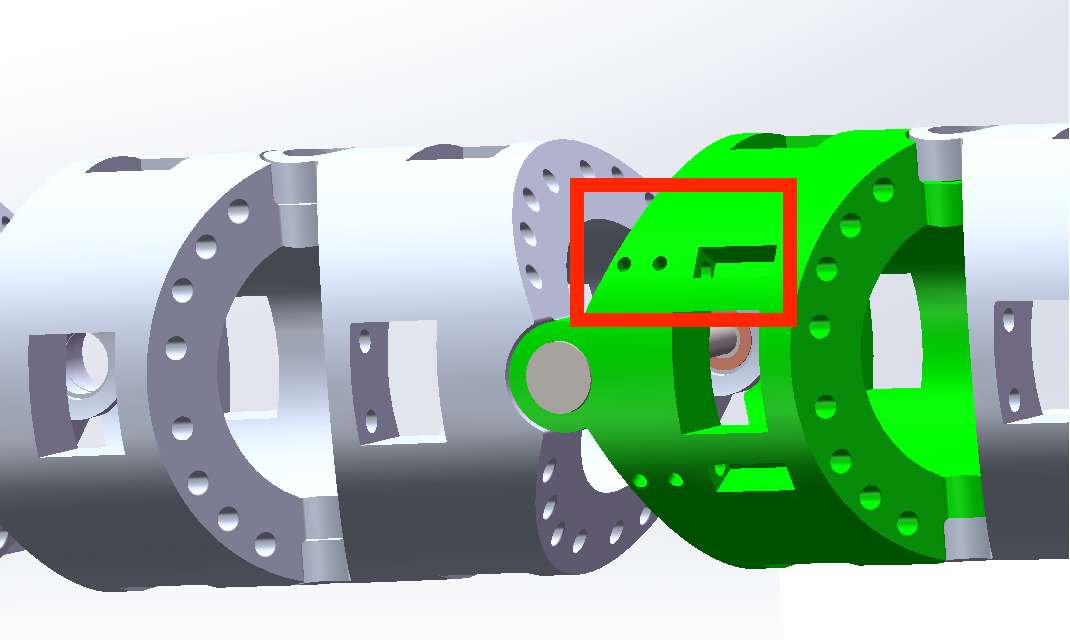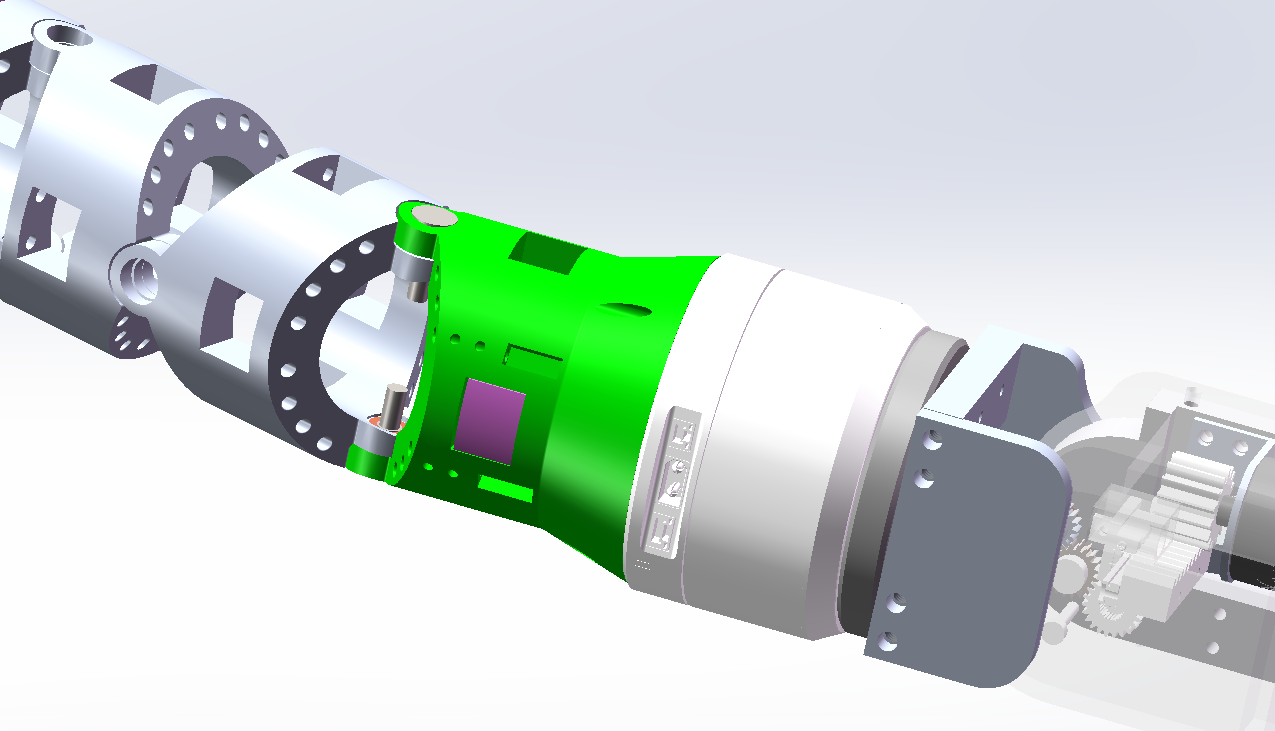

% % 特殊情况，每个关节和下一个关节连接处的圆盘内绳长（即绿色块内的绳长）需减掉一截Gap_4
% for i = 1:12
%     Rope_length(i) = Rope_length(i) - Gap_4(i);
% end

在新窗口运行下述各行，可得到相应结果：

tic;
for i =1:100
    Rope_intial=theta2rope ([0,0,0,0,0,0]);
    Rope_current =theta2rope([pi*5/180,pi*5/180,pi*5/180,pi*5/180,pi*5/180,pi*5/180]);
    Rope_current - Rope_intial;
end
toc;

历时 0.009978 秒。


Rope_length = theta2rope (theta)函数整体代码如下：

function Rope_length = theta2rope (theta)

%定义各间隙变量，相应地赋予固定值
Gap_1(1:12) = [0,0,0,0,0,0,0,0,0,0,0,0]; %第1个间隙
Gap_2(1:12) = [29.63,29.63,29.09,29.09,29.63,29.63,29.63,29.63,29.09,29.09,29.63,29.63]; %第2个间隙, 固定值
Gap_3(1:12) = [0,0,0,0,0,0,0,0,0,0,0,0]; %第3个间隙
Gap_4(1:12) = [29.63,29.63,29.09,29.09,29.63,29.63,29.63,29.63,29.09,29.09,29.63,29.63]; %第4个间隙, 固定值
Gap_base(1:12) = [24.57,24.57,26.11,26.11,28.12,28.12,28.12,28.12,26.11,26.11,24.57,24.57,];%基座圆盘处绳长，固定值

Rope_length=zeros(1, 12); %12根绳长的当前长度
beta = pi*50/180; % gap1和gap3的初始角度
R_Gap_1(1:12) = [23.03,23.03,18.82,18.82,13.33,13.33,13.33,13.33,18.82,18.82,23.03,23.03]; % 代表每个孔心在Gap1处到旋转轴的垂线长度
R_Gap_3(1:12) = [13.33,13.33,18.82,18.82,23.03,23.03,23.03,23.03,18.82,18.82,13.33,13.33]; % 代表每个孔心在Gap3处到旋转轴的垂线长度

% 第一节代表根部关节；
% 1，2,11,12

% 第一节的
%对12根绳都需计算
for N = 1:5
    for i = 1:12
        if i > 6
            Gap_1(i) = sin((beta-theta(1))/2) * 2*R_Gap_1(i);
        end
        if i <= 6
            Gap_1(i) = sin((beta+theta(1))/2) * 2*R_Gap_1(i);
        end

        if mod(i,2) ==1
            Gap_3(i) = sin((beta-theta(2))/2) * 2*R_Gap_3(i);
        end
        if mod(i,2) ==0
            Gap_3(i) = sin((beta+theta(2))/2) * 2*R_Gap_3(i);
        end

        Rope_length(i) = Rope_length(i) + Gap_1(i) + Gap_2(i) + Gap_3(i) + Gap_4(i)+Gap_base(i);
    end
end

% 第二节的
% 除了1,2,11,12
for N = 1:5
    for i = 1:12
        if(i==1 | i==2 | i ==11 | i ==12)
            Rope_length(i) = Rope_length(i) +0;

        else
            if i > 6
                Gap_1(i) = sin((beta-theta(3))/2) * 2*R_Gap_1(i);
            end
            if i <= 6
                Gap_1(i) = sin((beta+theta(3))/2) * 2*R_Gap_1(i);
            end

            if mod(i,2) ==1
                Gap_3(i) = sin((beta-theta(4))/2) * 2*R_Gap_3(i);
            end
            if mod(i,2) ==0
                Gap_3(i) = sin((beta+theta(4))/2) * 2*R_Gap_3(i);
            end

            Rope_length(i) =  Rope_length(i) + Gap_1(i) + Gap_2(i) + Gap_3(i) + Gap_4(i);
        end
    end
end

% 第三节的
% 除了1,2,11,12, 3,4,9,10
for N = 1:5
    for i = 1:12
        if(i == 1 | i == 2 | i == 11 | i == 12 | i == 3 | i == 4 | i == 9 | i == 10  )
            Rope_length(i) = Rope_length(i) +0;
        else
            if i > 6
                Gap_1(i) = sin((beta-theta(5))/2) * 2*R_Gap_1(i);
            end
            if i <= 6
                Gap_1(i) = sin((beta+theta(5))/2) * 2*R_Gap_1(i);
            end

            if mod(i,2) ==1
                Gap_3(i) = sin((beta-theta(6))/2) * 2*R_Gap_3(i);
            end
            if mod(i,2) ==0
                Gap_3(i) = sin((beta+theta(6))/2) * 2*R_Gap_3(i);
            end

            Rope_length(i) =  Rope_length(i) + Gap_1(i) + Gap_2(i) + Gap_3(i) + Gap_4(i);
        end
    end
end



% 特殊情况，每个关节和下一个关节连接处的圆盘内绳长（即绿色块内的绳长）需减掉一截Gap_4
for i = 1:12
    Rope_length(i) = Rope_length(i) - Gap_4(i);
end

end